% ===========================
%   DBF Payload Trade Study
% ===========================

clear; clc; close all;


% Givens
Ip1 = 6; Ip2 = 2;
Ic1 = 10; Ic2 = 8;
Ce = 10; Cp = 0.5; Cc = 2;
CLmax = 1;
CL_TO = CLmax * 0.8;
e = 0.7;
AR = 4;
CD0 = 0.2;
Cdi = 0.35^2 / (pi * e * AR);  %%
Sg = 150 * 0.3048;
w_pass = 0.65/16;   % passenger weight (lb)
w_cargo = 6/16;    % cargo weight (lb)
t_pass = 0.87;         % passenger time factor
t_cargo = 0.87;        % cargo time factor
lap_distance = 3000; % ft
banner_length = 10:60;
mu = 0.02;
CD_TO = 0.6;
ROC_ft = 250;           % ft/min
d1 = (ROC_ft * .3048);
n = 2.5;
g = 9.80665;             % m/s^2
rho = 1.198;
K = 1 / (pi * e * AR);
WS = linspace(1, 600, 500);
% Ranges for passengers and cargo
pass_range = 3:600;
cargo_range = 1:600;




%% ColorMap
color_pass  = [0, 0, 0] / 255;         % black
color_laps  = [172, 43, 55] / 255;     % red
color_cargo = [169, 176, 183] / 255;   % gray


n = 256;


n1 = round(n/2);
cmap1 = [linspace(color_pass(1), color_cargo(1), n1)', ...
         linspace(color_pass(2), color_cargo(2), n1)', ...
         linspace(color_pass(3), color_cargo(3), n1)'];


n2 = n - n1 + 1;
cmap2 = [linspace(color_cargo(1), color_laps(1), n2)', ...
         linspace(color_cargo(2), color_laps(2), n2)', ...
         linspace(color_cargo(3), color_laps(3), n2)'];


customMap = [cmap1; cmap2(2:end,:)];





% Volume per passenger / cargo (user-specified)
v_pass = 14.375;       % in^3
v_cargo = 2.25 * pi;   % in^3
vol_cap = 1500;        % in^3




%max_entries = 1e8;  % Estimate generously
results = []; %zeros(max_entries, 13);  % 13 columns as used
%row = 1;




% ===========================
%   Sweep over np, nc
% ===========================
for np = pass_range
    for nc = cargo_range
       payload = np * w_pass + nc * w_cargo;
       if payload > 6.4
           continue;
       end
       fuselage_v_p = np * v_pass + nc * v_cargo; % in^3
       fuselage_v = fuselage_v_p * 1.3;
       % Enforce 3 - 1 ratio
       if np < 3 * nc
           continue;
       end
       if fuselage_v < 125
           fuselage_v = 125;
       end
       % MTOW and EF
       MTOW = 9 + payload;
       Fuel = 100;
       Fuel_s = Fuel * 60 * 60;
       EF = Fuel/100;
       %V = sqrt(((26*(Fuel)-250)/(1.24*(fuselage_v/1728) + .702)));
       % laps = (3.28 * V * 300) ./ lap_distance;
       % laps_r = floor(laps);
       
       % ((.0664*V)+.448)

       V = 27; %% EDIT
       Vstall = V*(2/3);   
       V_TO   = 1.2 * Vstall;
       t1 = d1 / Vstall;
       ROC = (100 * .3048)/ t1;
       q_cruise = 0.5 * rho * V^2;
       q_to     = 0.5 * rho * V_TO^2;
       WS_stall = 0.5 * rho * Vstall^2 * CLmax;
       wingspan = sqrt((MTOW / (WS_stall/47.880258888889)) * AR);  % calc wingspan from stall constraint
       RAC = .05*(wingspan) + .75;
       TW_takeoff = (V_TO^2) / (2*g*Sg) ...
                + (q_to * CD_TO) ./ WS ...
                + mu * (1 - (q_to * CL_TO) ./ WS);
       TW_cruise = (q_cruise * CD0) ./ WS ...
                + WS ./ (q_cruise * pi * e * AR);
       TW_ROC = ROC / V ...
                + (q_cruise * CD0) ./ WS ...
                + K * WS ./ q_cruise;
       TW_turn = q_cruise * ((CD0 ./ WS) + K * ( ((n ./ q_cruise)^2) * WS ));

       %calculate laps
       D = 0.5 * rho * V^2 * (MTOW * 4.44822 / (WS_stall)) * (Cdi + CD0);
       laps = (Fuel_s * 0.40 * 0.75 * 0.9) / (D * 3000 * 0.3048);
       laps_r = floor(laps);
       % if wingspan > 5 *.3048
       %     continue;
       % end
       % EF Enforcement
       if EF < 0.25
           EF = 0.25;
       end
       if EF > 1
           continue;
       end
       % if wingspan < 3 * .3048
       %    continue;
       % end
       

       % Income
       Income = (np * (Ip1 + (Ip2 * laps_r))) + (nc * (Ic1 + (Ic2 * laps_r)));
   
       % Cost
       Cost = laps_r * (Ce + (np * Cp) + (nc * Cc)) * EF;
   
       % Net Income
       NI = Income - Cost;
   
       % GM score
       GM = (7.5*2 + 8) / ((2*((np * t_pass) + (nc * t_cargo) +4.02))+8);
       M3 = ((laps_r*60)/RAC);
       % Total Score
       %TS = 1 + (NI/) + GM + M3;
   
       % Payload volume
       vol = np * v_pass + nc * v_cargo;
       if vol > vol_cap
           continue;
       end
       % --- inside loop ---
       % just store NI, don’t try to normalize yet
       %results(row, :) = [np, nc, payload, EF, NI, GM, NaN, vol, laps_r, M3, bl, wingspan, fuselage_v];
       %row = row + 1;
       % Store row
       results = [results; np, nc, payload, EF, NI, GM, NaN, vol, laps_r, M3, 60, wingspan, fuselage_v, V, Vstall, WS_stall/47.880258888889, D, MTOW];     
     end
 end



if isempty(results)
   error('No feasible configurations found. Check constraints or ranges.');
end


maxNI = max(results(:,5));
maxM3 = max(results(:,10));



results(:,7) = 1 + (results(:,5)/maxNI) + results(:,6) + 2 + (results(:,10)/maxM3);


% ===========================
%   Convert to Table
% ===========================
results_table = array2table(results, ...
  'VariableNames', {'Passengers','Cargo','Payload_lb','EF','NetIncome','GM','TotalScore','Volume_in3','Laps','Mission 3','Banner Length','Wingspan', 'Fuselage Volume', 'Velocity', 'Stall', 'Loading', 'Drag', 'MTOW'});




% Sort by Total Score (descending)
sorted_results = sortrows(results_table, 'TotalScore', 'descend');
sorted_results1 = sortrows(results_table, 'NetIncome', 'descend');
sorted_results2 = sortrows(results_table, 'Cargo', 'descend');
% Display top 10
disp('===== Top 50 Configurations by Total Score =====');

===== Top 50 Configurations by Total Score =====


disp(sorted_results(1:min(50, height(sorted_results)), :));

    Passengers    Cargo    Payload_lb    EF    NetIncome      GM       TotalScore    Volume_in3    Laps    Mission 3    Banner Length    Wingspan    Fuselage Volume    Velocity    Stall    Loading     Drag      MTOW 
    __________    _____    __________    __    _________    _______    __________    __________    ____    _________    _____________    ________    _______________    ________    _____    _______    

disp('===== Top 50 Configurations by Net Income =====');

===== Top 50 Configurations by Net Income =====


disp(sorted_results1(1:min(50, height(sorted_results)), :));

    Passengers    Cargo    Payload_lb    EF    NetIncome      GM       TotalScore    Volume_in3    Laps    Mission 3    Banner Length    Wingspan    Fuselage Volume    Velocity    Stall    Loading     Drag      MTOW 
    __________    _____    __________    __    _________    _______    __________    __________    ____    _________    _____________    ________    _______________    ________    _____    _______    

disp('===== Top 50 Configurations by Pucks =====');

===== Top 50 Configurations by Pucks =====


disp(sorted_results2(1:min(50, height(sorted_results)), :));

    Passengers    Cargo    Payload_lb    EF    NetIncome      GM       TotalScore    Volume_in3    Laps    Mission 3    Banner Length    Wingspan    Fuselage Volume    Velocity    Stall    Loading     Drag      MTOW 
    __________    _____    __________    __    _________    _______    __________    __________    ____    _________    _____________    ________    _______________    ________    _____    _______    

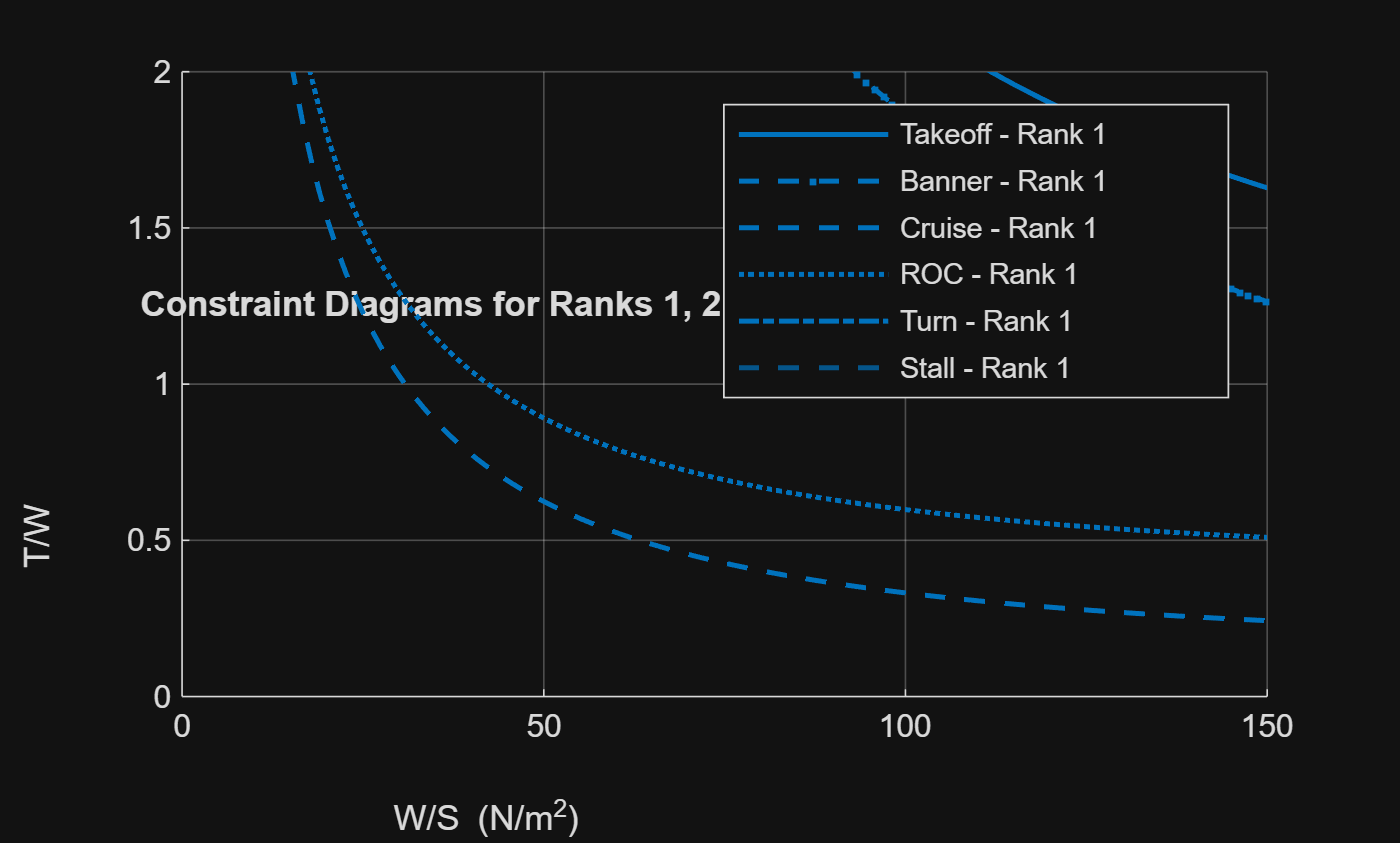



ranks = [1];
configs = sorted_results(ranks, :);


% ===========================
%   Plots
% ===========================


figure; hold on; grid on;
colors = lines(length(ranks));  % Distinct colors for each rank


for i = 1:length(ranks)
   cfg = configs(i,:);
  
   % Extract values
   payload = cfg.Payload_lb;
   wingspan = cfg.Wingspan;
   fuselage_v = cfg.Volume_in3;
   EF = cfg.EF;
  
   MTOW = 7.9;
   Fuel = 6.11 * MTOW - 2.29;
   %V = sqrt(((26*(Fuel)-250)/(1.24*(fuselage_v/1728) + .702)));
   V = 27;
   L = 7;
   CD0 = .07;
   Wth = L/5;
   BWeight = Wth*L*.048;
   CDB = .1;
   Vstall = V * (2/3);
   V_TO = 1.2 * Vstall;
   q_cruise = 0.5 * rho * V^2;
   q_to = 0.5 * rho * V_TO^2;
   WS_stall = 0.5 * rho * Vstall^2 * CLmax;


   TW_takeoff = (V_TO^2) / (2*g*Sg) ...
                + (q_to * CD_TO) ./ WS ...
                + mu * (1 - (q_to * CL_TO) ./ WS);
   TW_cruise = (q_cruise * CD0) ./ WS ...
                + WS ./ (q_cruise * pi * e * AR);
   TW_cruise_banner = ((q_cruise * CD0 *(CDB*Wth*L/.163))) ./ (WS) ...
                + (WS) ./ (q_cruise * pi * e * AR);
   TW_ROC = ROC / V ...
                + (q_cruise * CD0) ./ WS ...
                + K * WS ./ q_cruise;
   TW_turn = q_cruise * ((CD0 ./ WS) + K * ( ((n ./ q_cruise)^2) * WS ));


   % Plot each constraint curve
   plot(WS, TW_takeoff, 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Takeoff - Rank %d', ranks(i)));
   plot(WS, TW_cruise_banner, '--.', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Banner - Rank %d', ranks(i)));
   plot(WS, TW_cruise, '--', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Cruise - Rank %d', ranks(i)));
   plot(WS, TW_ROC, ':', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('ROC - Rank %d', ranks(i)));
   plot(WS, TW_turn, '-.', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Turn - Rank %d', ranks(i)));
   xline(WS_stall, '--r', 'Color', colors(i,:), 'LineWidth', 1.5, 'DisplayName', sprintf('Stall - Rank %d', ranks(i)));
end


xlabel('W/S (N/m^2)');
ylabel('T/W');
title('Constraint Diagrams for Ranks 1, 2, and 3');
legend show;
xlim([0 150]);
ylim([0 2]);



% ===========================
%   Second Plot: Imperial Units
% ===========================


WS_imperial = WS * 0.020885;         % Convert wing loading to lbf/ft^2
WS_stall_imperial = WS_stall * 0.020885;


figure; hold on; grid on;
for i = 1:length(ranks)
   cfg = configs(i,:);
  
   % Recompute values (same as before)
   payload = cfg.Payload_lb;
   wingspan = cfg.Wingspan;
   fuselage_v = cfg.Volume_in3;
   EF = cfg.EF;
  
   MTOW = payload + 9.57;
   Fuel = 6.11 * MTOW - 2.29;
   V = 27*3.281
   % sqrt(((26*(Fuel)-250)/(1.24*(fuselage_v/1728) + .702)));
   
   Vstall = V * (2/3);
   V_TO = 1.2 * Vstall;
   q_cruise = 0.5 * rho * V^2;
   q_to = 0.5 * rho * V_TO^2;
  
   TW_takeoff = (V_TO^2) / (2*g*Sg) ...
              + (q_to * CD_TO) ./ WS ...
              + mu * (1 - (q_to * CL_TO) ./ WS);


   TW_cruise = (q_cruise * CD0) ./ WS ...
             + WS ./ (q_cruise * pi * e * AR);


   TW_ROC = ROC / V ...
          + (q_cruise * CD0) ./ WS ...
          + K * WS ./ q_cruise;


   TW_turn = q_cruise * ((CD0 ./ WS) + K * ((n ./ q_cruise)^2) * WS);


   % Plot each constraint curve using WS_imperial
   plot(WS_imperial, TW_takeoff, 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Takeoff - Rank %d', ranks(i)));
   plot(WS_imperial, TW_cruise, '--', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Cruise - Rank %d', ranks(i)));
   plot(WS_imperial, TW_ROC, ':', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('ROC - Rank %d', ranks(i)));
   plot(WS_imperial, TW_turn, '-.', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Turn - Rank %d', ranks(i)));
   xline(WS_stall_imperial, '--r', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Stall - Rank %d', ranks(i)));
end

V = 88.5870

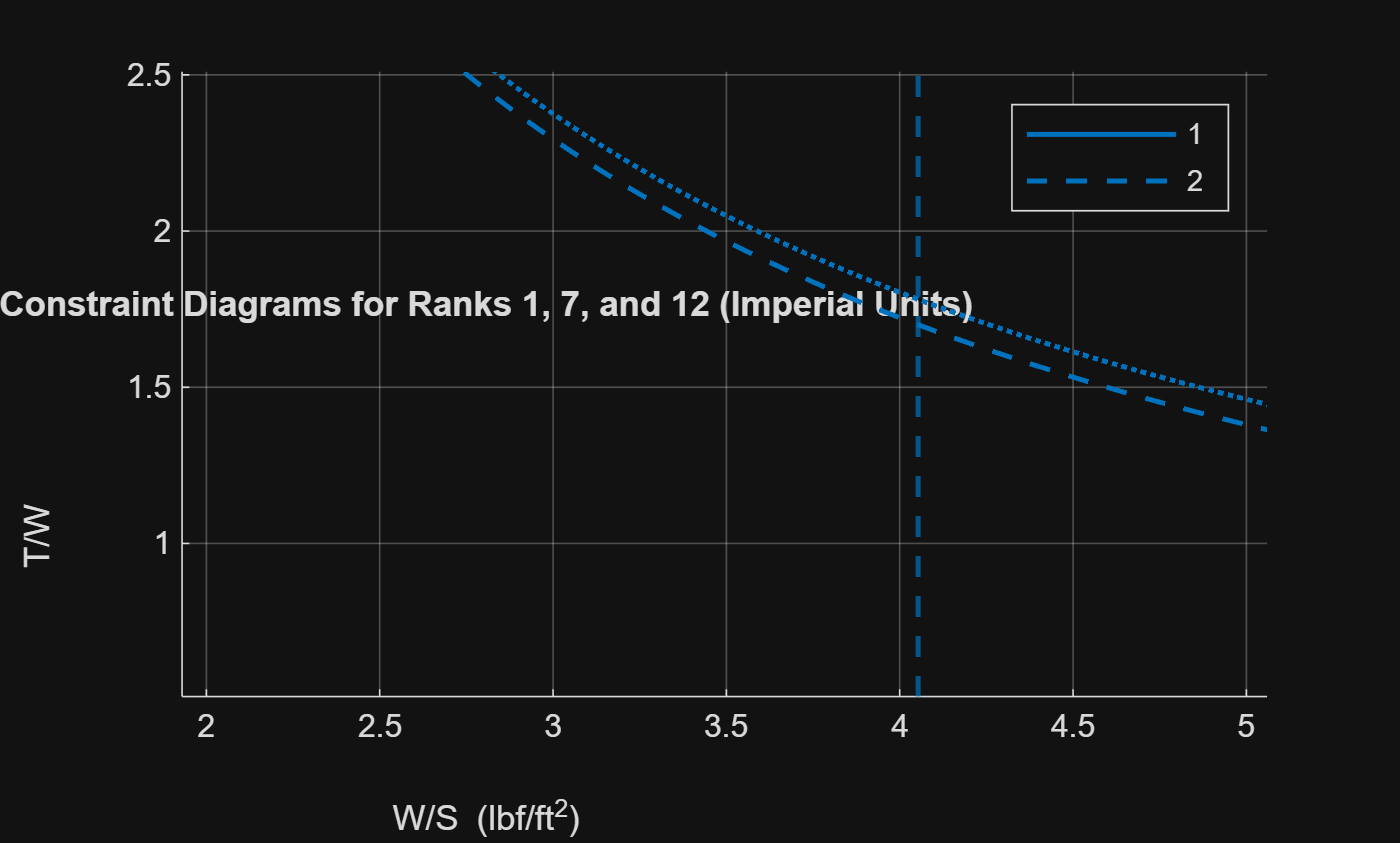



xlabel('W/S (lbf/ft^2)');
ylabel('T/W');
title('Constraint Diagrams for Ranks 1, 7, and 12 (Imperial Units)');
legend('1', '2');
xlim([0 150 * 0.020885]);  % Adjusted x-axis limit
ylim([0 2]);

xlim([1.93 5.06])
ylim([0.51 2.51])

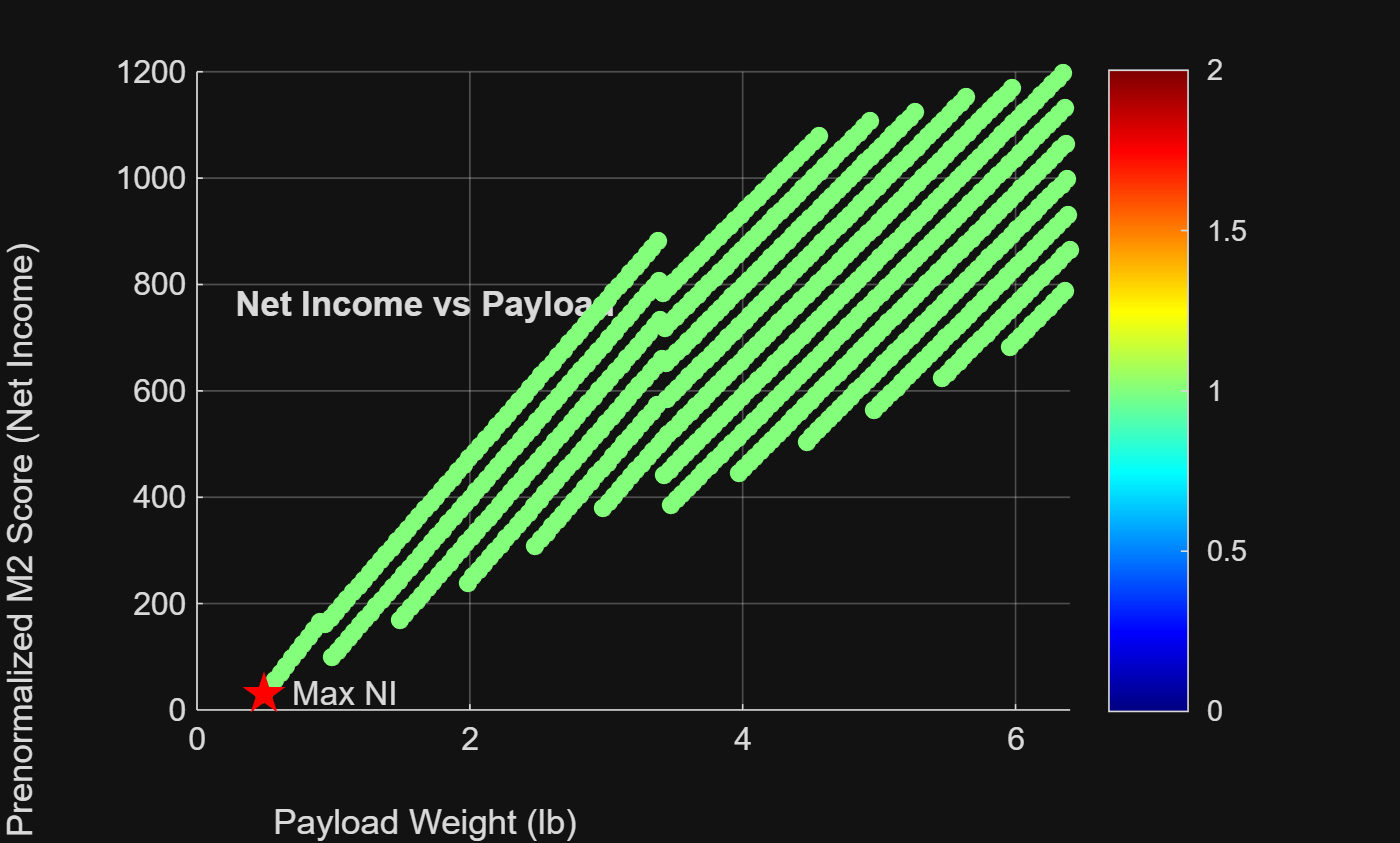

% Net Income vs Payload
figure; hold on; grid on;
scatter(results(:,3), results(:,5), 30, results(:,4), 'filled');
xlabel('Payload Weight (lb)');
ylabel('Prenormalized M2 Score (Net Income)');
title('Net Income vs Payload');
colorbar; colormap jet;
plot(sorted_results.Payload_lb(1), sorted_results.NetIncome(1), 'rp', 'MarkerSize',12,'MarkerFaceColor','r');
text(sorted_results.Payload_lb(1)+0.2, sorted_results.NetIncome(1)+0.1, 'Max NI');

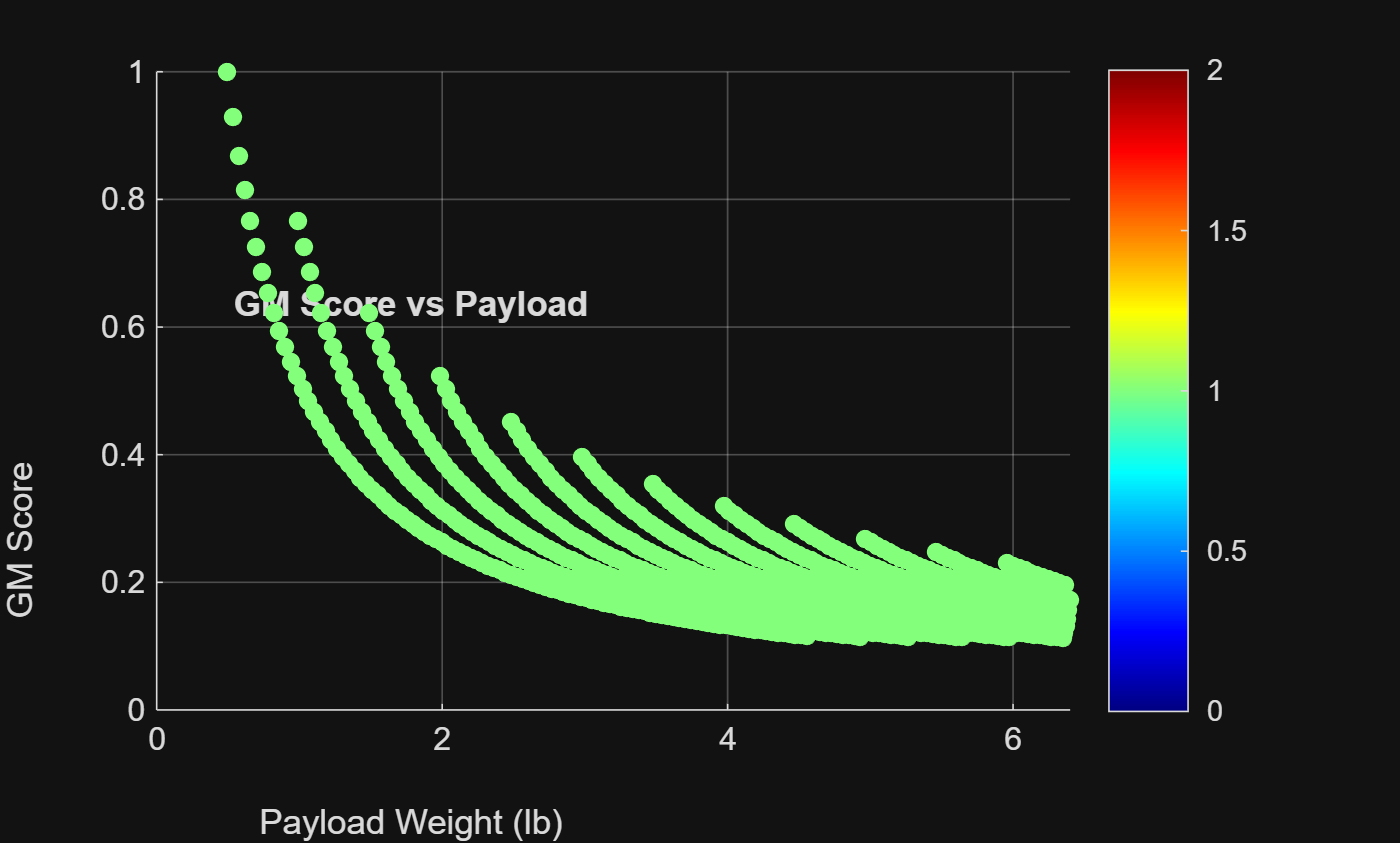





% GM vs Payload
figure; hold on; grid on;
scatter(results(:,3), results(:,6), 30, results(:,4), 'filled');
xlabel('Payload Weight (lb)');
ylabel('GM Score');
title('GM Score vs Payload');
colorbar; colormap jet;

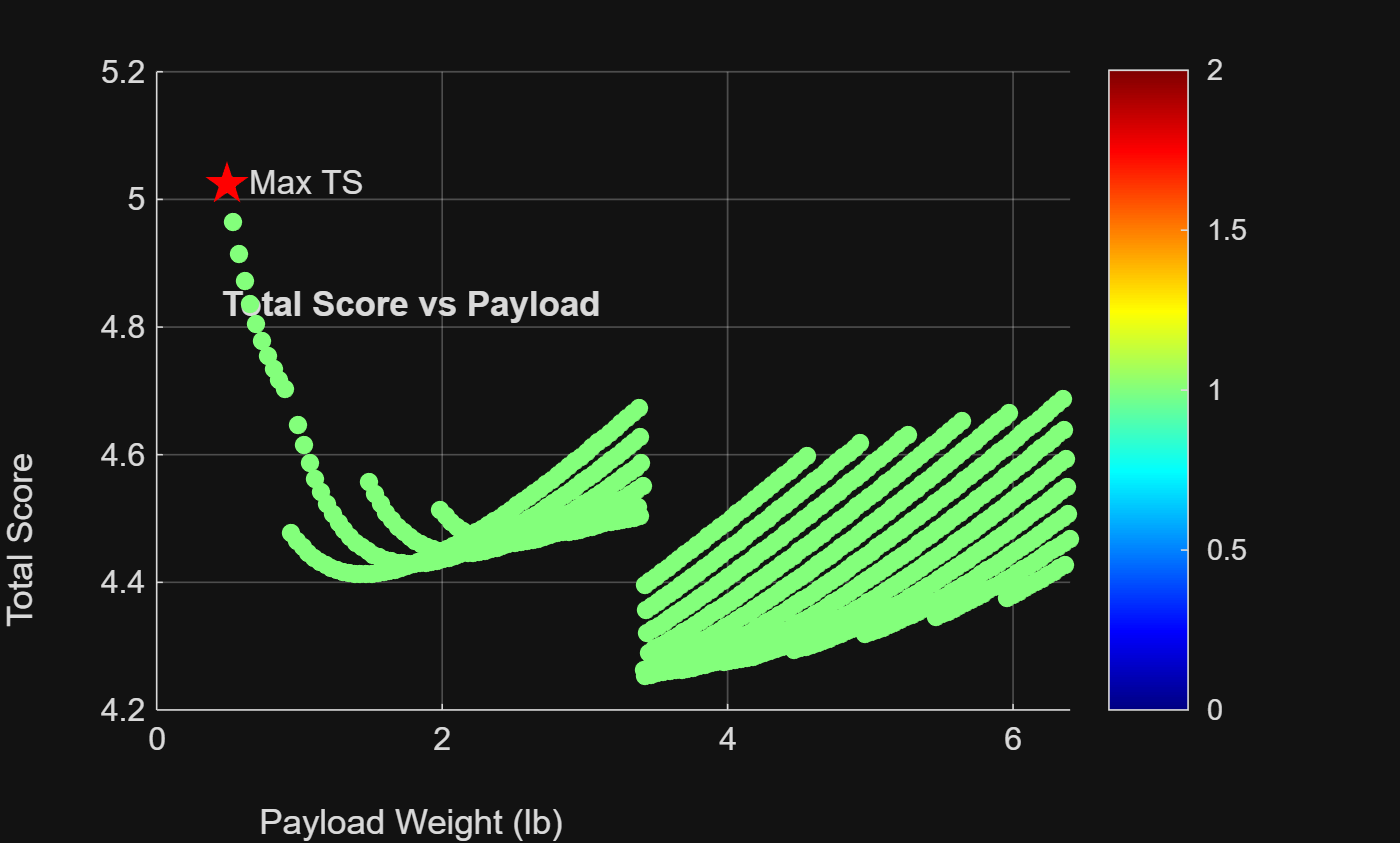





% Total Score vs Payload
figure; hold on; grid on;
scatter(results(:,3), results(:,7), 30, results(:,4), 'filled');
xlabel('Payload Weight (lb)');
ylabel('Total Score');
title('Total Score vs Payload');
colorbar; colormap jet;
plot(sorted_results.Payload_lb(1), sorted_results.TotalScore(1), 'rp', 'MarkerSize',12,'MarkerFaceColor','r');
text(sorted_results.Payload_lb(1)+0.15, sorted_results.TotalScore(1), 'Max TS');

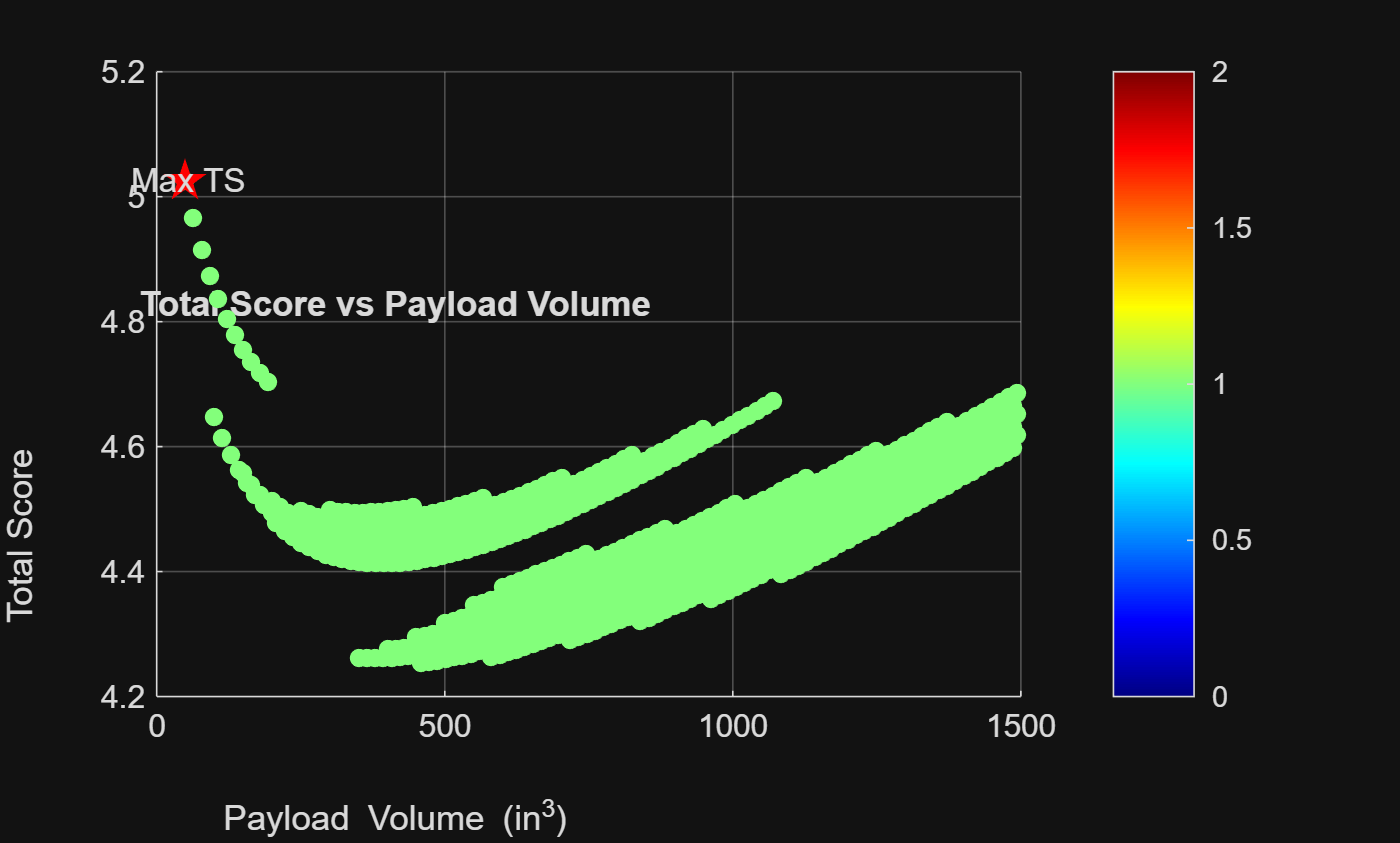





% Total Score vs Volume
figure; hold on; grid on;
scatter(results(:,8), results(:,7), 30, results(:,4), 'filled');
xlabel('Payload Volume (in^3)');
ylabel('Total Score');
title('Total Score vs Payload Volume');
colorbar; colormap jet;
plot(sorted_results.Volume_in3(1), sorted_results.TotalScore(1), 'rp', 'MarkerSize',12,'MarkerFaceColor','r');
text(sorted_results.Volume_in3(1)-95, sorted_results.TotalScore(1), 'Max TS');

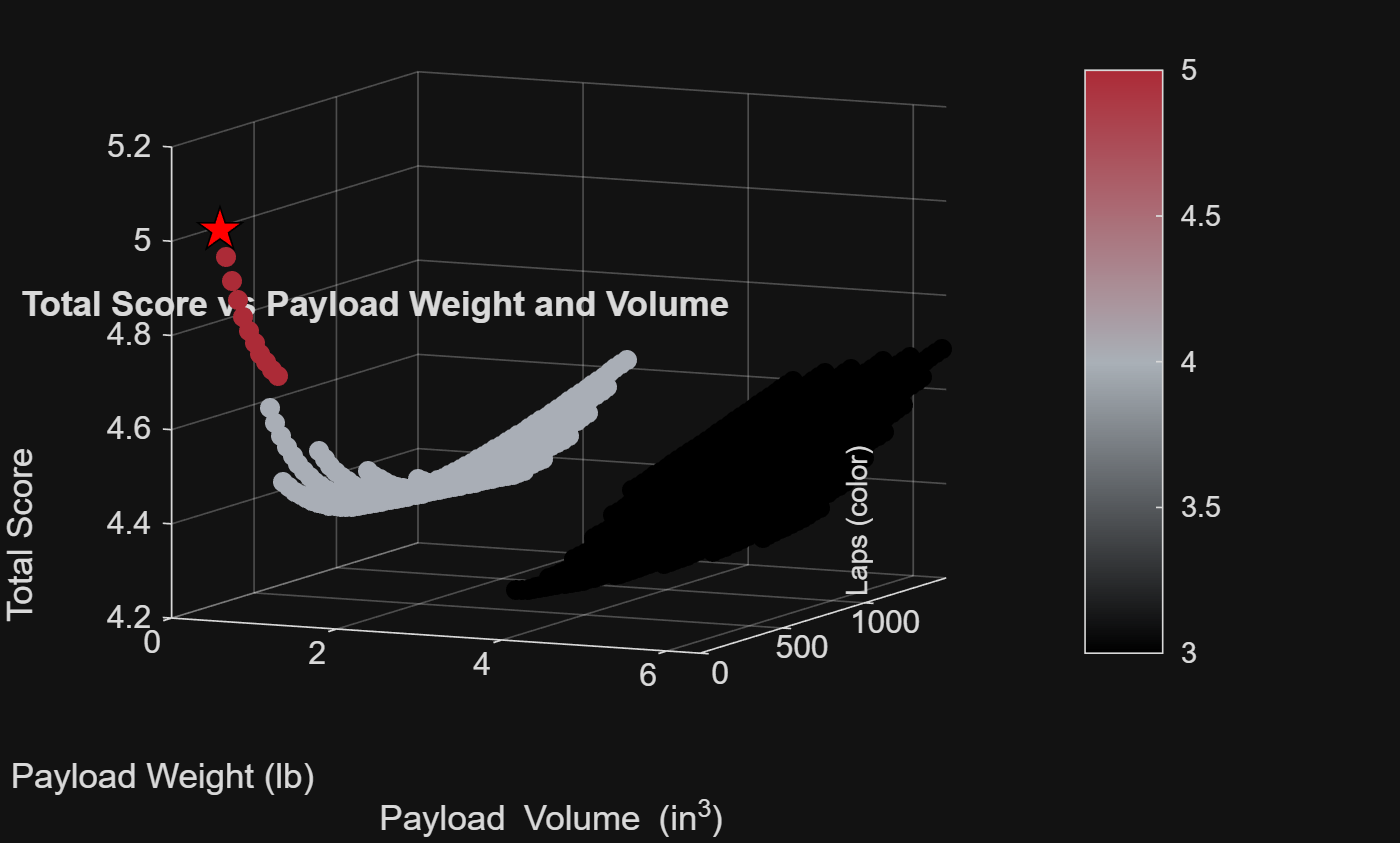





% 3D Scatter
figure; hold on; grid on;
scatter3(results(:,3), results(:,8), results(:,7), 36, results(:,9), 'filled');
xlabel('Payload Weight (lb)');
ylabel('Payload Volume (in^3)');
zlabel('Total Score');
title('Total Score vs Payload Weight and Volume');
plot3(sorted_results.Payload_lb(1), sorted_results.Volume_in3(1), sorted_results.TotalScore(1), ...
    'kp', 'MarkerSize',14, 'MarkerFaceColor','r');
text(sorted_results.Payload_lb(1)-30, sorted_results.Volume_in3(1), sorted_results.TotalScore(1), 'Max TS');
view(25,10);
colorbar_handle = colorbar;
colorbar_handle.Label.String = 'Laps (color)';
colormap(customMap);


saveas(gcf, fullfile('C:\Users\gmbol\OneDrive\School Work\MQP', 'Total Score vs Payload Weight and Volume Sensitivity (LAPS CONS).png'));

Error using saveas (line 138)
Invalid or missing path: C:\Users\gmbol\OneDrive\School Work\MQP\Total Score vs Payload Weight and Volume Sensitivity (LAPS CONS).png




% ===========================
%   Bar Chart of Top 10
% ===========================
figure; hold on; grid on;
bar(categorical(string(1:50)), sorted_results.TotalScore(1:50));
xlabel('Top 10 Configurations (Rank)');
ylabel('Total Score');
title('Top 30 Configurations by Total Score');











